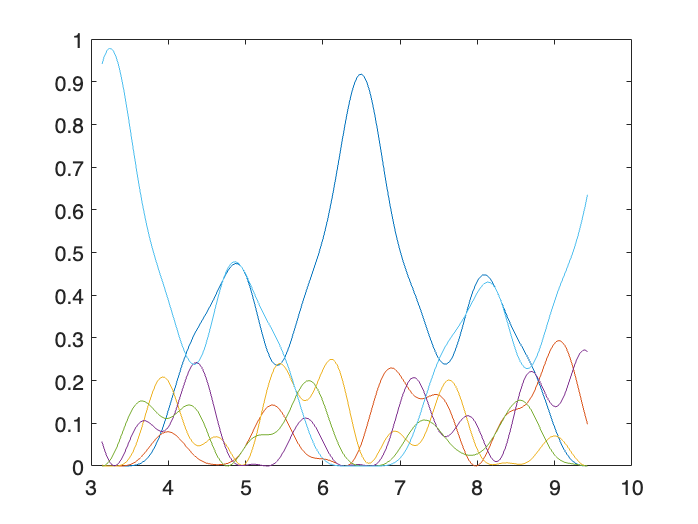

clear all;
sigmax=spinOp(5/2,'x');
sigmay=spinOp(5/2,'y');
sigmaz=spinOp(5/2,'z');
initial=transpose([1 0 0 0 0 0]);
timelist=[1:0.01:3].*pi;

ham=sigmax+0.95*sigmax^2;

for i=1:length(timelist)
    time=timelist(i);
    finalstate(i,:)=ham_evolve(ham,initial,time);
end

figure;
for j=1:6
    plot(timelist,abs(finalstate(:,j)).^2);
    hold on;
end
ylim([0 1]);

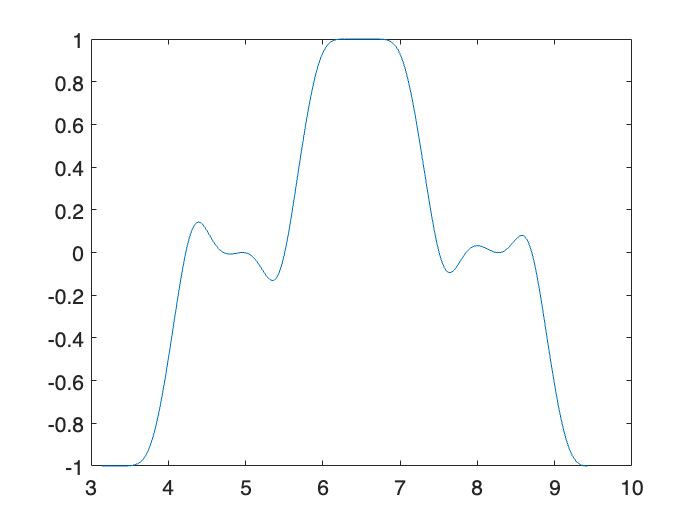



phase=(abs(finalstate(:,1)).^2-abs(finalstate(:,6)).^2)...
    ./(abs(finalstate(:,1)).^2+abs(finalstate(:,6)).^2);
figure;
plot(timelist,phase);

function final=ham_evolve(ham,initial,time)
try
    final=expm(-1i*ham*time)*initial;
catch 
    disp("Wrong Solution!!");
end
end